# Practicum Control Theory 1 – Q1 Week 1-2

## Prerequisite 

In the course Control Theory 1 (CT1) we will use Matlab intensively. To make sure all participants have some basic knowledge of Matlab, please make sure, if you have not done that before, to take the Matlab Onramp course: [https://nl.mathworks.com/learn/tutorials/matlab-onramp.html](https://nl.mathworks.com/learn/tutorials/matlab-onramp.html). After successfull completion of this course, which will take you at most two hours, you will receive a personal certificate. 

Matlab makes use of toolboxes. The Symbolic Math toolbox will be used frequently in this course. Please do the self-pace course at [https://nl.mathworks.com/learn/tutorials/introduction-to-symbolic-math-with-matlab.html.](https://nl.mathworks.com/learn/tutorials/introduction-to-symbolic-math-with-matlab.html.) Of course, you are free to do all parts of this course, but parts 7.1, 7.2 9.1, 9.2, 10.1, 10.2, 11.2, 11.3, 11.4 and 12 are optional as those aspects will not be used in the Control Theory course. Also after completing this course, which will take 1 hour max, you will receive a personal certificate.

Make sure you hand in the two certificates to your teacher.

## Practical assignments

*Requirements: Matlab R2018a or higher with the Symbolic Math Toolbox*

In the first two weeks you will get acquainted with the symbolic Math Toolbox to define functions, compute Laplace transforms and perform partial fraction decompositions. These assignments give you the means to check your own skills in computing Laplace transforms and partial fraction decompositions. 

When handing in the assignment both answers (by hand and by Matlab) must be handed in AND both answers to the same question should correspond to each other.

### Basics of function definition

To define a function in Matlab using the Symbolic Math Toolbox, e.g. $f(t) = t$, you execute the following code:

syms t
f(t) = t;

This function can now be evaluated at all values of $t$ e.g. $t=1$. 

 f(1)

$$ans = 1$$

which will return the value 1 in the example. To plot the function $f$ in the Symbolic Math Toolbox, you can simply call      

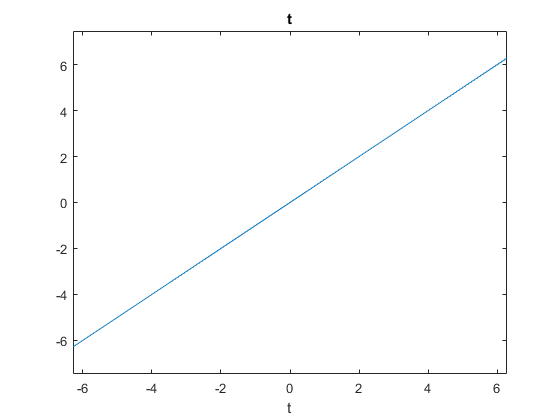

ezplot(f)

Please study the manual on `ezplot` to discover additional options to restrict the domain and range of the function drawn. Try it.

### Laplace transform

The Symbolic Math Toolbox has the functionality to perform the Laplace transform of a given function. For example

syms t
f = exp(-t);
laplace(f)

$$ans = \frac{1}{s+1}$$

provides the Laplace transform of the function $f(t) = e^{-t}$. Please study the manual on `laplace` to see more examples.

#### Assignments Laplace Transform 

*Compute the Laplace transform by hand or by looking up their corresponding transformation in the table of the following functions*

- 
$$f(t) = t^5$$


- 
$$g(t) = \cos(4t)$$


- 
$$h(t) = e^{9t}$$


- 
$$k(t) = \sin(5t)$$


- 
$$l(t) = e^{-3t}\sin(5t)$$


- 
$$m(t) = t\sin(4t)$$


- 
$$n(t) = \frac{t^2}{e^{4t}}$$


- 
$$p(t) = \frac{\sin(5t)}{e^{6t}}$$


- 
$$q(t) = e^{t/2}\cos\left(\frac{t}{2}\right)$$


*and verify your answers using the Symbolic Math Toolbox.*

### Partial fraction decomposition

To define a function in Matlab using the Symbolic Math Toolbox, which consists of fractions, as a typical Laplace transform will look like, you need to take special care of brackets. For example, $F(s) = \frac{s+2}{s^2-1}$, you execute the following code:  

syms s
F(s) = (s+2)/(s^2-1);

To display this function in a more familiar way, you can use the `pretty` command:

pretty(F(s))

 s + 2
------
 2
s  - 1



To extract the numerator and denominator from a function, the Symbolic Math Toolbox has the `numden` function to separate them. By calling 

[N, D] = numden(F(s))

$$N = s+2$$

$$D = s^{2}-1$$

you get `N = s + 2` and `D = s^2 - 1`. This gives you the means to analyze the denominator separately. For example, you can find the zeros of the denominator with the command

factor(D)

$$ans = \left(\begin{array}{cc} s-1 & s+1 \end{array}\right)$$

which returns `D = [ s - 1, s + 1]`, which means that $s^2-1 = (s-1)(s+1)$.

Before the inverse Laplace transform can be applied, we need to perform partial fraction decomposition. The Symbolic Math Toolbox has the `partfrac` function built-in:

partfrac(F(s))

$$ans = \frac{3}{2\,\left(s-1\right)}-\frac{1}{2\,\left(s+1\right)}$$

which returns `3/(2*(s - 1)) - 1/(2*(s + 1))` for the example.

#### Assignments Partial Fraction Decomposition 

*Perform by hand the partial fraction decomposition of the following functions:*

- 
$$F(s) = \frac{s^2-4s+3}{s^3-s^2-s+1}$$


- 
$$G(s) = \frac{5s^2-5s+5}{s^3-2s^2-s+2}$$


- 
$$H(s) = \frac{14}{s^4-s^3-s^2-2s}$$
  

*and verify your answers using the Symbolic Math Toolbox****.***